% Clear workspace and command window
clear; clc; close all;

%% 1. Initialize and Load the Network
inp_file = 'Net1.inp'; 
d = epanet(inp_file);

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.



%% 2. Configure Water Quality Parameters & Injection Pattern
d.setQualityType('CHEM', 'mg/L'); 

% --- MODIFIED: LOWER DECAY RATES SO CHEMICAL TRAVELS FURTHER ---
num_links = d.getLinkCount;
d.setLinkBulkReactionCoeff(ones(1, num_links) * -0.05); % Lower decay (-0.05 1/day)
d.setLinkWallReactionCoeff(ones(1, num_links) * -0.1);  % Lower wall decay

% --- FIXED INJECTION PATTERN ARRAY ---
% 6 Hours ON (2.0 mg/L) followed by 6 Hours OFF (0 mg/L), repeating for 24 hours
cyclic_multipliers = [2.0, 2.0, 2.0, 2.0, 2.0, 2.0, 0, 0, 0, 0, 0, 0, 2.0, 2.0, 2.0, 2.0, 2.0, 2.0, 0, 0, 0, 0, 0, 0];
d.addPattern('CYCLIC_INJ', cyclic_multipliers);
pattern_idx = d.getPatternIndex('CYCLIC_INJ');

% Identify source nodes (Node ID '9' and the absolute top node)
node_ids = d.getNodeNameID;
coords_cell = d.getNodeCoordinates;
[~, top_node_idx] = max(coords_cell{2}); 
id_9_idx = find(strcmp(node_ids, '9'));
source_nodes = unique([top_node_idx, id_9_idx]);

for idx = source_nodes
    d.setNodeSourceType(idx, 'CONCEN');
    d.setNodeSourcePatternIndex(idx, pattern_idx);
    d.setNodeSourceQuality(idx, 1.0); 
end

%% 3. Execute Complete Hydraulic & Quality Simulation
d.solveCompleteHydraulics;

% Open and initialize water quality engine
d.openQualityAnalysis;
d.initializeQualityAnalysis(1); 

tleft = 1;
step_index = 1;
time_steps = [];
node_quality_history = [];

while tleft > 0
    d.runQualityAnalysis;
    
    total_duration = d.getTimeSimulationDuration;
    time_steps(step_index) = (total_duration - tleft) / 3600;
    node_quality_history(:, step_index) = d.getNodeActualQuality;
    
    tleft = d.stepQualityAnalysisTimeLeft;
    step_index = step_index + 1;
end

d.closeQualityAnalysis;
disp('Simulation complete.');

Simulation complete.


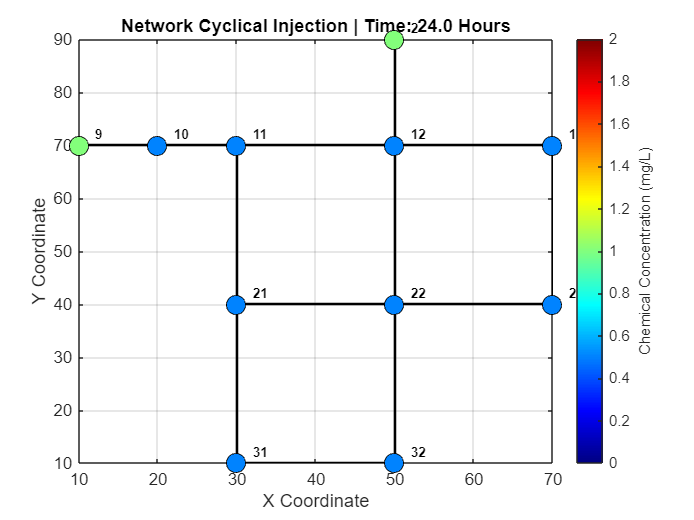

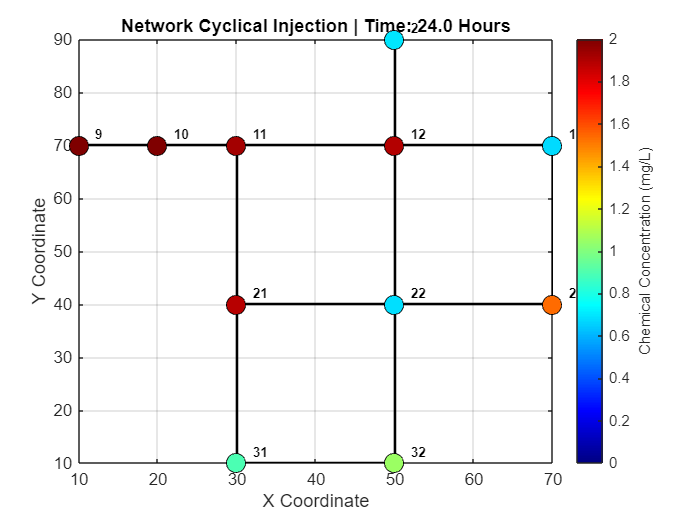


%% 4. Playback Spatial Chemical Wave Animation
x_coords = coords_cell{1}; 
y_coords = coords_cell{2}; 
link_nodes = d.getLinkNodesIndex; 

fig = figure('Name', 'Pulsing Water Quality Animation', 'NumberTitle', 'off');
max_val = max(node_quality_history(:));
if max_val <= 0, max_val = 2.0; end 

for t = 1:length(time_steps)
    clf(fig); 
    hold on; grid on; box on;
    
    % Draw pipe framework
    for i = 1:num_links
        from_node = link_nodes(i, 1);
        to_node = link_nodes(i, 2);
        plot([x_coords(from_node), x_coords(to_node)], ...
             [y_coords(from_node), y_coords(to_node)], ...
             'k-', 'LineWidth', 1.5);
    end
    
    % Render nodes color-coded by their active chemical concentration
    spatial_quality = node_quality_history(:, t);
    scatter(x_coords, y_coords, 130, spatial_quality, 'filled', 'MarkerEdgeColor', 'k');
    
    colormap('jet'); 
    clim([0, max_val]); 
    cb = colorbar;
    ylabel(cb, 'Chemical Concentration (mg/L)');
    
    title(['Network Cyclical Injection | Time: ', num2str(time_steps(t), '%.1f'), ' Hours']);
    xlabel('X Coordinate'); ylabel('Y Coordinate');
    
    for i = 1:d.getNodeCount
        text(x_coords(i) + 2, y_coords(i) + 2, node_ids{i}, 'FontSize', 8, 'FontWeight', 'bold');
    end
    
    hold off;
    drawnow;   
    pause(0.15); 
end

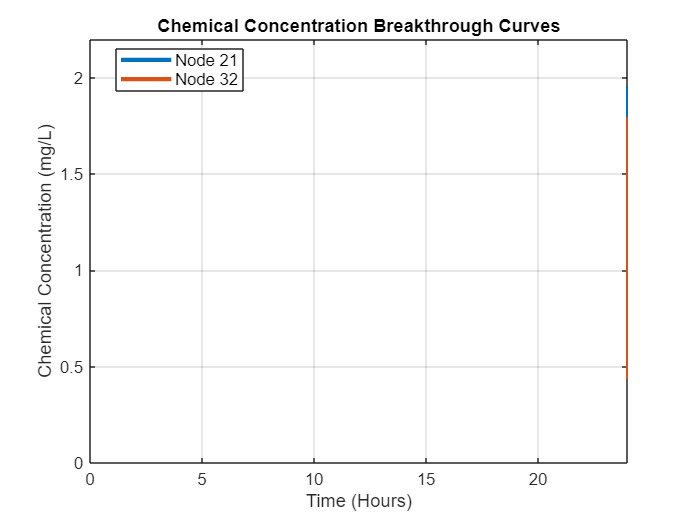

%% 6. Plot Concentration Breakthrough Curves Over Time
% Let's select two interesting nodes to compare: 
% Node 21 (middle of the network) and Node 32 (at the very bottom)
nodes_to_analyze = {'21', '32'}; 

figure('Name', 'Node Concentration Profiles', 'NumberTitle', 'off');
hold on; grid on; box on;

for i = 1:length(nodes_to_analyze)
    % Find the internal index for the text ID
    target_idx = find(strcmp(node_ids, nodes_to_analyze{i}));
    
    if ~isempty(target_idx)
        % Extract the 24-hour concentration history for this specific node
        node_curve = node_quality_history(target_idx, :);
        
        % Plot the timeline graph
        plot(time_steps, node_curve, 'LineWidth', 2.5, ...
             'DisplayName', ['Node ' nodes_to_analyze{i}]);
    end
end

% Formatting the line graph
title('Chemical Concentration Breakthrough Curves');
xlabel('Time (Hours)');
ylabel('Chemical Concentration (mg/L)');
xlim([0, max(time_steps)]);
ylim([0, max(node_quality_history(:)) + 0.2]);
legend('Location', 'best', 'FontSize', 10);
hold off;


d.unload;

EPANET Class is unloaded
